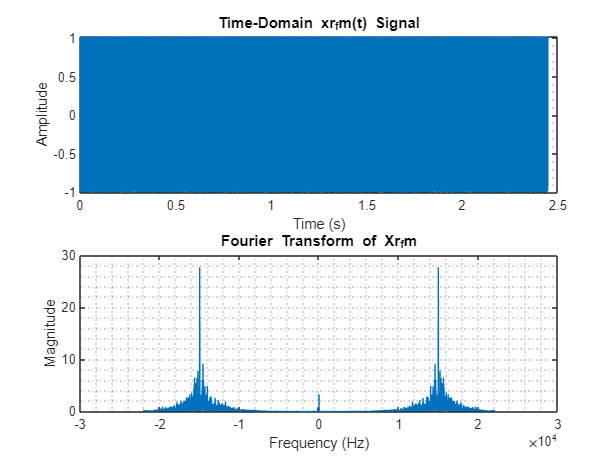

%1.5.2-frequency modulation 
%1.3 
%z=0.02
delta_f=10*10^3; 
v_fm=fmmod(v_m,fc,fs,delta_f);
xr_fm=v_fm+z;
Xr_fm=fftshift(fft(xr_fm))/sqrt(N);

subplot(2,1,1)
plot(t,xr_fm)
hold on 
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain xr_fm(t) Signal');
grid minor
hold off
subplot(2,1,2)
plot(f,abs(Xr_fm))
hold on 
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Fourier Transform of Xr_fm');
grid minor
hold off

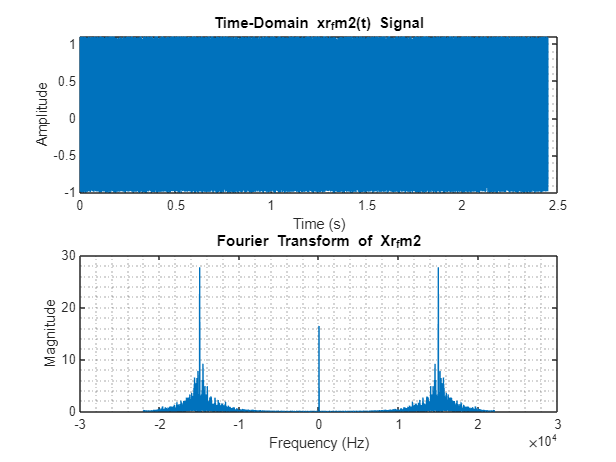

clf
%z=0.1

xr_fm2=v_fm+z2;
Xr_fm2=fftshift(fft(xr_fm2))/sqrt(N);

subplot(2,1,1)
plot(t,xr_fm2)
hold on 
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain xr_fm2(t) Signal');
grid minor
hold off
subplot(2,1,2)
plot(f,abs(Xr_fm2))
hold on 
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Fourier Transform of Xr_fm2');
grid minor
hold off

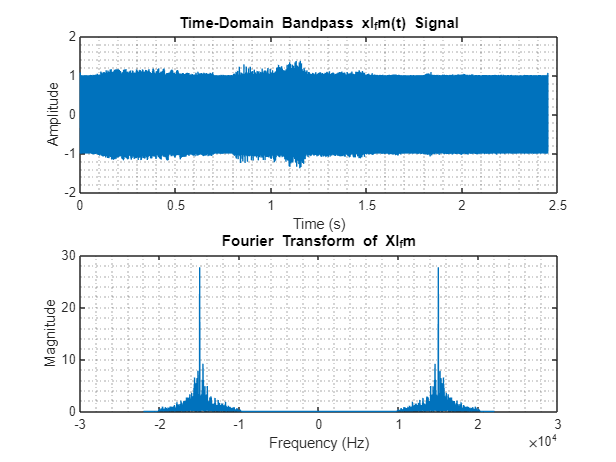

clf

%^%%1.4.1-fm modulation
xl_fm=bandpass(xr_fm,[10000,20000],fs);
Xl_fm=fftshift(fft(xl_fm))/sqrt(N);
xl_fm2=bandpass(xr_fm2,[10000,20000],fs);
Xl_fm2=fftshift(fft(xl_fm2))/sqrt(N);


subplot(2,1,1)
plot(t,xl_fm)
hold on 
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain Bandpass xl_fm(t) Signal');
grid minor
hold off
subplot(2,1,2)
plot(f,abs(Xl_fm))
hold on 
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Fourier Transform of Xl_fm');
grid minor
hold off

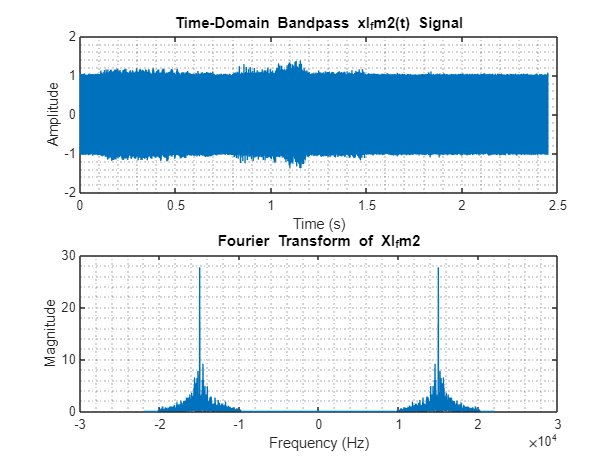

clf
subplot(2,1,1)
plot(t,xl_fm2)
hold on 
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain Bandpass xl_fm2(t) Signal');
grid minor
hold off
subplot(2,1,2)
plot(f,abs(Xl_fm2))
hold on 
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Fourier Transform of Xl_fm2');
grid minor
hold off

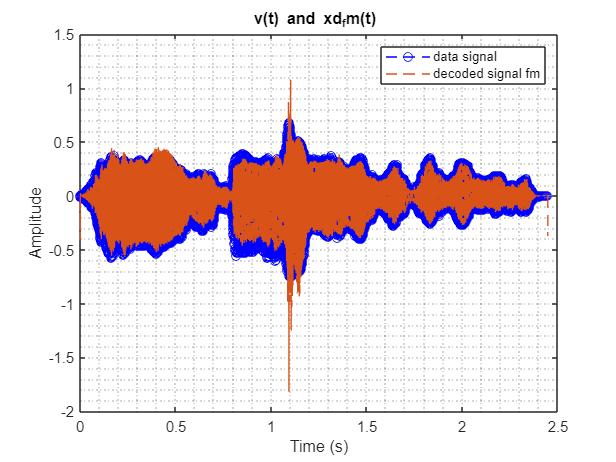

clf

xd_fm=fmdemod(xl_fm,fc,fs,delta_f);
xd_fm2=fmdemod(xl_fm2,fc,fs,delta_f);


Xd_fm=fftshift(fft(xd_fm))/sqrt(N);
Xd_fm2=fftshift(fft(xd_fm2))/sqrt(N);

plot(t, v_m, 'b--o');
hold on;
plot(t, xd_fm,'--');
xlabel('Time (s)');
ylabel('Amplitude');
title('v(t) and xd_fm(t) ');
legend('data signal', 'decoded signal fm');
grid minor
hold off

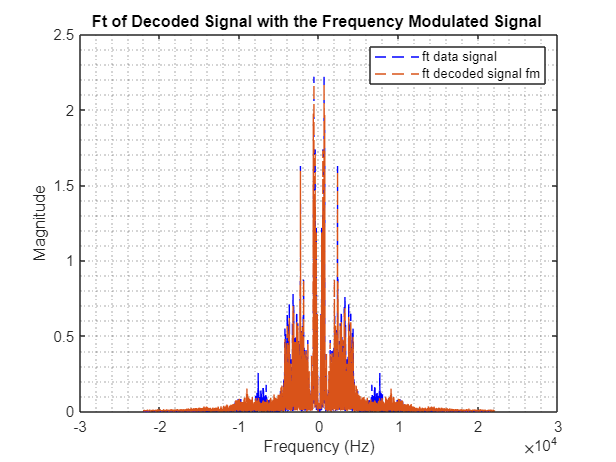

clf
plot(f, abs(V_m), 'b--');
hold on;
plot(f, abs(Xd_fm),'--');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Ft of Decoded Signal with the Frequency Modulated Signal ');
grid minor
legend('ft data signal', 'ft decoded signal fm');
hold off

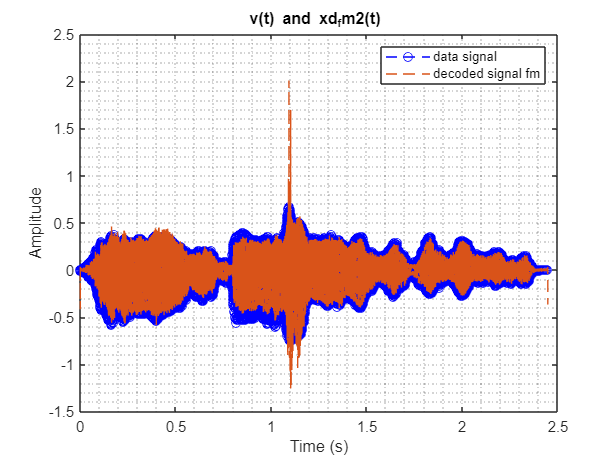

clf
sound(xd_fm,fs)
plot(t, v_m, 'b--o');
hold on;
plot(t, xd_fm2,'--');
xlabel('Time (s)');
ylabel('Amplitude');
title('v(t) and xd_fm2(t) ');
legend('data signal', 'decoded signal fm');
grid minor
hold off

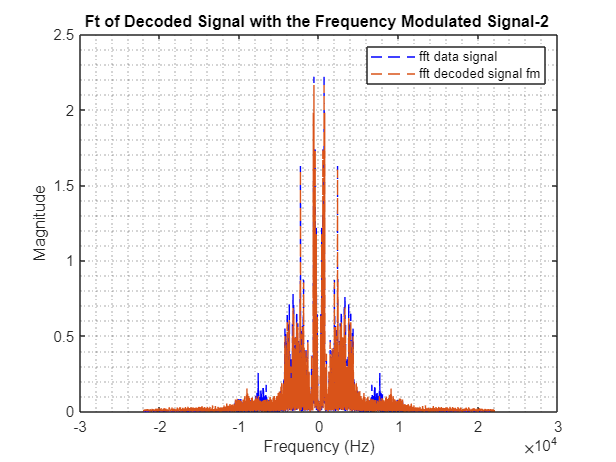

clf
plot(f, abs(V_m), 'b--');
hold on;
plot(f, abs(Xd_fm2),'--');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Ft of Decoded Signal with the Frequency Modulated Signal-2 ');
grid minor
legend('fft data signal', 'fft decoded signal fm');
hold off

clf
correlation_factor3=xcorr(xd_fm,v_m,0,'coeff');
correlation_factor4=xcorr(xd_fm2,v_m,0,'coeff');
data = [correlation_factor1; correlation_factor2; correlation_factor3; correlation_factor4];
names={'correlation_factor1','correlation_factor2','correlation_factor3','correlation_factor4'}';
tab=table(names,data,'VariableNames',{'correlation factor','value'});
disp(tab)

      correlation factor        value 
    _______________________    _______

    {'correlation_factor1'}    0.98826
    {'correlation_factor2'}    0.96778
    {'correlation_factor3'}    0.97671
    {'correlation_factor4'}    0.97306

